# **IO755 & IO756 - Ethernet/IP Loopback**

The IO755 and IO756 are Ethernet/IP I/O modules to connect real-time target machines to industrial equipment. The IO755 is an Ethernet/IP Scanner module that is used to communicate with field-level devices such as motor controllers and sensors. The IO756 is an Ethernet/IP Adapter module that is used to communicate with devices on the control and process level such as programmable logic controllers. The modules handle the complete data exchange between the real-time application and the connected devices. The data exchange is processed via a dual-port memory. Each module acts as one Ethernet/IP station exclusively. The two Ethernet connectors enable easy network integration.

Ethernet/IP communication typically takes place between one Ethernet/IP Scanner and multiple Ethernet/IP Adapters. In this example, one scanner (IO755) communicates with one adapter (IO756), installed in the same machine. The modules are configured to exchange generic values.

The IO755 requires configuration files (included with this example). The files are created with SYCON.net, a software tool from Hilscher.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO755 and one IO756 installed

- CAT5 Ethernet cable or newer

The IO755 requires configuration files. These files come with the example model and do not have to be created. However, the SYCON.net project is also included in the example and can be used to recreate the configuration files. The module help documentation and the SYCON documentation explain how to use SYCON.net, which is free of charge. Find the download link in the Additional References section below.

### Test Setup

Ethernet/IP is an Ethernet-based protocol. Use a CAT5 cable or newer to connect the IO755 with the IO756. Both modules have 2 connectors. It does not matter which one you use.

The configuration files (*.nxd) for the IO755 are automatically packed into the real-time application by the build process and unpacked during the initialization of the real-time application on the target.

## Initialize and Open the Simulink Model

 
% Sample time
Ts = 0.001;

% Open Simulink model
modelName = 'sgMdl_IO755_IO756_EthernetIPLoopback';
open_system(modelName);

### Model Description

The model sets up the communication for both the IO755 and IO756. When starting the model, the [IO755 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io755_setup) block loads the corresponding configuration files onto the I/O module. The IO756 is entirely configured by the [IO756 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io756) block. The Receive and Send blocks are used to exchange data.

The IO756 is configured to send 11 bytes to the IO755. Within this payload, the data is structured as follows:

- Constant signal of type int16

- Counter signal of type uint32

- Sine wave of type single

- Pulse signal of type uint8

The model illustrates how to use [Byte Packing](https://www.mathworks.com/help/slrealtime/io_ref/bytepacking.html) blocks to pack the signals into one byte array to be processed by the Send block. [Byte Unpacking](https://www.mathworks.com/help/slrealtime/io_ref/byteunpacking.html) blocks are used to extract the signals from the byte array that the Receive block outputs.

The IO755 is configured to send 15 bytes to the IO756. Within this payload, the data is structured as follows:

- Constant signal of type int8

- Counter signal of type uint16

- Sine wave of type double

- Pulse signal of type int32

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Wait until connection is established
pause(5);

% Prepare the Simulink Data Inspector to plot signals
Simulink.sdi.clearAllSubPlots;
Simulink.sdi.setSubPlotLayout(2,2);
Simulink.sdi.view;

% Start the real-time application
tg.start;

% Select the signals for plotting, set the axis limits and line colors
sdiRunIDs = Simulink.sdi.getAllRunIDs;
sdiLatestRun = Simulink.sdi.Run.getLatest;
s = sdiLatestRun.getSignalsByName('S2M_Counter');
plotOnSubPlot(s,1,1,true);
s = sdiLatestRun.getSignalsByName('S2M_Pulse');
plotOnSubPlot(s,1,1,true);
s = sdiLatestRun.getSignalsByName('S2M_Sine');
plotOnSubPlot(s,1,2,true);
s = sdiLatestRun.getSignalsByName('S2M_Constant');
plotOnSubPlot(s,1,2,true);
s = sdiLatestRun.getSignalsByName('M2S_Counter');
plotOnSubPlot(s,2,1,true);
s = sdiLatestRun.getSignalsByName('M2S_Pulse');
plotOnSubPlot(s,2,1,true);
s = sdiLatestRun.getSignalsByName('M2S_Sine');
plotOnSubPlot(s,2,2,true);
s = sdiLatestRun.getSignalsByName('M2S_Constant');
plotOnSubPlot(s,2,2,true);

% set limits
Simulink.sdi.setSubplotLimits(1,1,'AllRange',[0,10,-10,110]);
Simulink.sdi.setSubplotLimits(1,2,'AllRange',[0,10,-110,110]);
Simulink.sdi.setSubplotLimits(2,1,'AllRange',[0,10,-10,110]);
Simulink.sdi.setSubplotLimits(2,2,'AllRange',[0,10,-110,110]);


### Check the Results

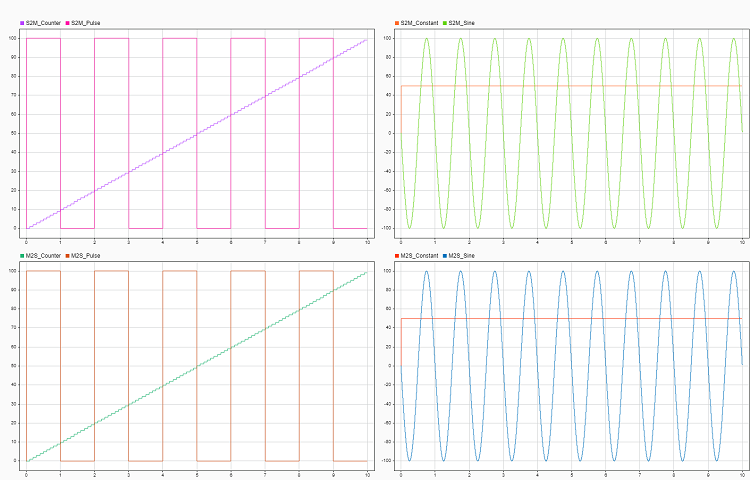

## Additional References

- [IO755 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io755)

- [IO756 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io756)